## Middle Interval [1, 1000] anlaysis

#### Compare the number of guesses people take to the number of guesses a bisection search algorith would take

% logical vector of whether person knows bisection search
class = logical([1, 1, 0, 0, 1, 0, 1, 0, 0, 1, 0, 1, 1, 1, 0, 1, 0, 1,...
    1, 1, 1, 1, 0, 0, 1, 0, 1, 1, 0, 0, 0, 1, 0, 0, 0, 0, 1, 1, 1, 0, 1, 0, 1]); % 1 if participant knew Bisection Search

people_nTurns = [12, 9, 16, 15, 12, 8, 3, 4, 12, 10, 13, 8, 15, 11, 10, 16,...
    20, 13, 10, 9, 11, 9, 7, 20, 28, 10, 13, 10, 9, 11, 34, 13, 8, 25, 13, 9, 10, 6, 10, 8, 12, 10, 10]';

machine_nTurns = [10, 10, 8, 8, 9, 10, 3, 9, 9, 8, 10, 10, 8, 10, 9, 9, 10, 8, 10, ...
    8, 8, 9, 10, 8, 8, 10, 10, 8, 10, 7, 10, 8, 10, 8, 10, 10, 6, 8, 8, 9, 6, 8, 8]'; 
% Bisection Search has worst-case complexity of O(logN). note that 10 ~= log(1000)

[mean(people_nTurns), var(people_nTurns)]

ans =    12.1395   34.4086


[mean(machine_nTurns),  var(machine_nTurns)]

ans =     8.6744    2.0343


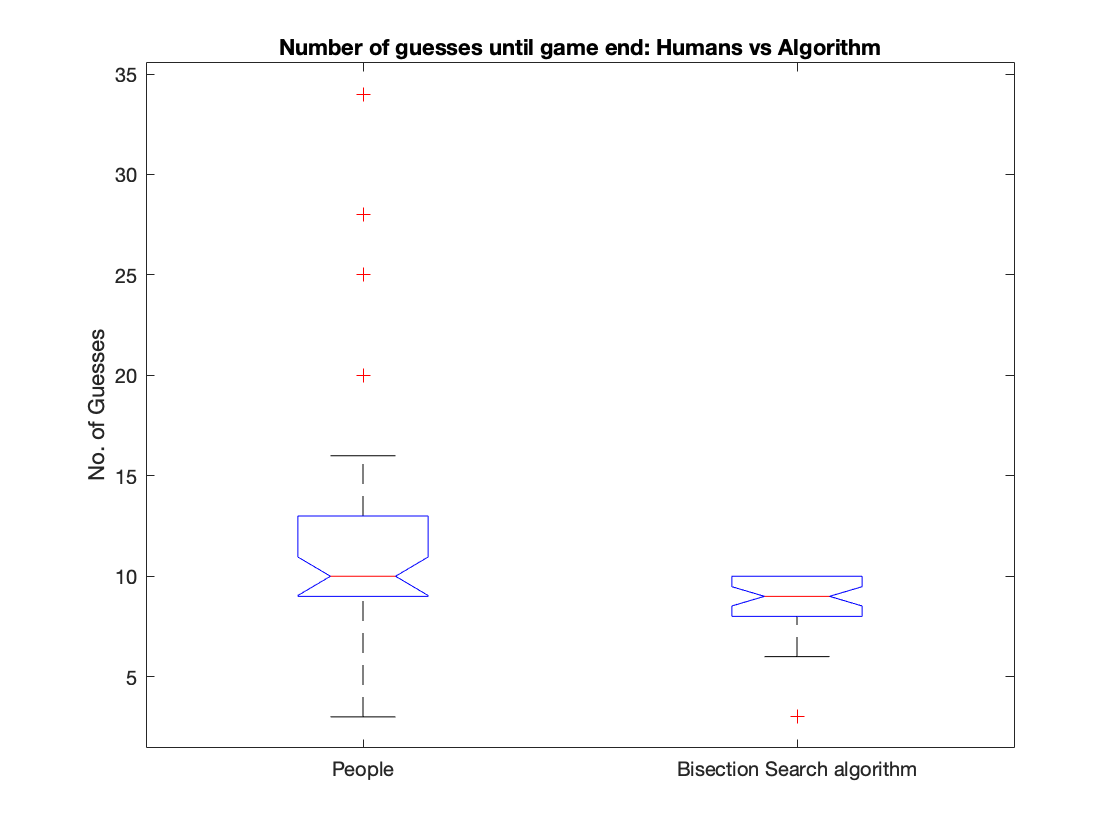


figure
boxplot([people_nTurns, machine_nTurns],'Notch','on','Labels', ...
    {'People', 'Bisection Search algorithm'})
ylabel('No. of Guesses')
title("Number of guesses until game end: Humans vs Algorithm")
hold off


% % compare people who knew bisection search to those who did not
% [mean(people_nTurns(class)), var(people_nTurns(class))]
% [mean(people_nTurns(~class)),  var(people_nTurns(~class))]
% 
% figure
% boxplot(people_nTurns, class, 'Notch','on','Labels', ...
%     {'heard of Bisection Search', 'never heard of Bisection Search'})
% title("Number of guesses until game end: Prior-knowledge vs Agnostic")
% hold off

#### Look at the absolute deviation of people from an EIG maximizing agent

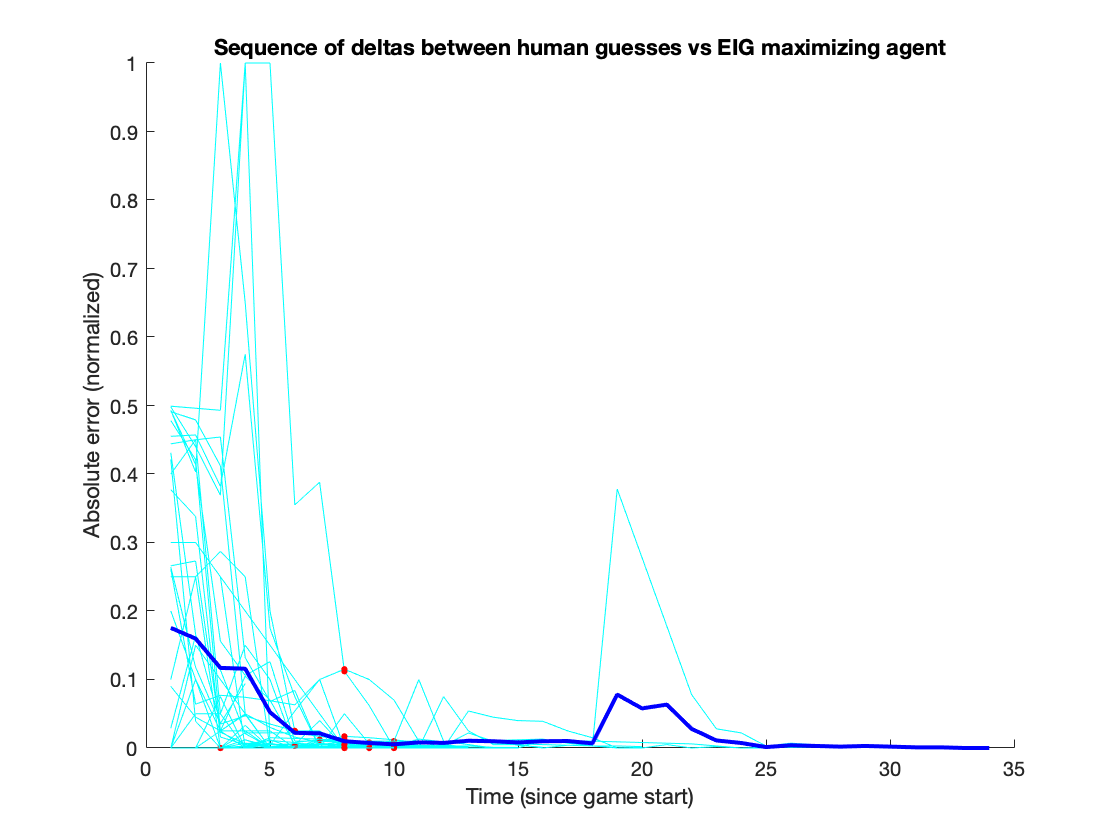

% a cell array of the absolute errors from imformation maximizing bisection
% search at each guess
deltas = {[90, 45, 25, 49, 0, 0, 3, 2, 0, 1, 1, 0] ;
[0, 0, 0, 33, 0, 0, 1, 0, 0] ;
[493, 414, 156, 106, 126, 10, 10, 17, 15, 12, 8, 7, 12, 10, 5, 0] ;
[100, 250, 0, 7, 5, 6, 6, 5, 5, 4, 4, 3, 3, 1, 1] ;
[0, 0, 0, 12, 0, 7, 5, 9, 8, 7, 2, 1] ;
[300, 300, 250, 0, 0, 2, 2, 0] ;
[0, 0, 0] ;
[431, 166, 36, 94] ;
[0, 150, 100, 50, 0, 0, 3, 2, 0, 2, 1, 1] ;
[0, 0, 0, 7, 0, 0, 0, 0, 0, 0] ;
[478, 421, 25, 105, 70, 5, 40, 1, 4, 3, 3, 2, 2] ;
[0, 0, 25, 0, 5, 5, 0, 1] ;
[444, 450, 454, 132, 68, 84, 0, 0, 5, 5, 0, 5, 0, 0, 0] ;
[0, 0, 25, 25, 0, 0, 3, 3, 0, 0, 0] ;
[400, 450, 50, 150, 100, 0, 5, 5, 4, 1] ;
[0, 0, 0, 12, 0, 3, 0, 8, 6, 5, 4, 3, 22, 10, 4, 1] ;
[300, 300, 250, 200, 150, 100, 50, 0, 0, 3, 13, 9, 10, 11, 12, 13, 7, 3, 0, 1] ;
[491, 479, 412, 50, 0, 0, 0, 0, 5, 2, 0, 0, 0] ;
[0, 0, 0, 2, 5, 2, 3, 0, 0, 0] ;
[0, 0, 0, 22, 22, 22, 17, 12, 2] ;
[0, 0, 75, 0, 0, 0, 7, 0, 0, 2, 1] ;
[0, 150, 100, 50, 30, 16, 8, 0, 0] ;
[377, 338, 16, 5, 2, 1, 1] ;
[498, 440, 369, 1000, 1000, 355, 388, 112, 62, 0, 0, 75, 25, 5, 5, 0, 4, 3, 3, 2] ;
[499, 496, 493, 1000, 4, 54, 100, 115, 100, 70, 10, 0, 54, 45, 40, 39, 25, 15, 0, 0, 5, 0, 2, 0, 1, 1, 1, 0] ;
[200, 100, 25, 25, 25, 0, 0, 3, 0, 1] ;
[455, 457, 382, 575, 175, 75, 0, 50, 6, 4, 1, 1, 1] ;
[250, 250, 287, 250, 0, 7, 0, 0, 0, 0] ;
[0, 0, 25, 25, 0, 0, 1, 1, 1] ;
[266, 273, 23, 6, 11, 8, 12, 8, 1, 1, 0] ;
[261, 64, 77, 74, 69, 63, 100, 0, 5, 10, 10, 7, 12, 7, 6, 5, 4, 3, 378, 278, 178, 78, 28, 22, 3, 7, 5, 4, 3, 2, 1, 1, 0, 0] ;
[0, 0, 75, 0, 0, 0, 13, 10, 10, 10, 9, 5, 1] ;
[421, 39, 0, 0, 12, 0, 3, 1] ;
[493, 403, 1000, 650, 200, 25, 25, 0, 10, 10, 100, 10, 5, 0, 0, 11, 11, 10, 9, 8, 7, 6, 3, 0, 0] ;
[0, 0, 25, 50, 0, 0, 10, 8, 0, 0, 2, 1, 1] ;
[0, 50, 50, 0, 15, 14, 13, 5, 0] ;
[0, 0, 0, 12, 2, 3, 1, 1, 0, 0] ;
[0, 100, 0, 12, 2, 2] ;
[0, 0, 25, 0, 0, 7, 0, 0, 2, 1] ;
[29, 164, 114, 21, 1, 3, 2, 0] ;
[264, 118, 35, 47, 35, 25, 23, 0, 5, 5, 2, 4] ;
[0, 0, 25, 0, 0, 3, 3, 0, 0, 0] ;
[0, 0, 0, 3, 7, 0, 0, 5, 0, 1]};

% deltas = deltas(~class); % by default analyze everyone

% a matrix of where each column is a participant's error sequence
M = nan(length(deltas), max(cellfun(@length, deltas)));
% plot the trajectory of the errors (both types of people)
figure
hold on
for i = 1:length(deltas)
    M(i, 1:length(deltas{i})) = deltas{i};
    plot(deltas{i}/1000, 'LineWidth', 0.5, 'Color', 'cyan')
    % pure bisection search would have stopped at red dots
    x = machine_nTurns(i);
    if machine_nTurns(i) <= length(deltas{i})
        y = deltas{i}(x)/1000; 
    else 
        y = 0;
    end
    plot(x, y, 'r.', 'MarkerSize', 8)
end
M = M';
% create an array of the delta averages
average_deltas = nanmean(M,2);
% plot the average error sequence
plot(average_deltas/1000, 'LineWidth', 2, 'Color', 'blue')
title("Sequence of deltas between human guesses vs EIG maximizing agent")
xlabel('Time (since game start)')
ylabel('Absolute error (normalized)')
hold off 

#### Use Bayesian inference to estimate the shape parameter, k, of the error data modelled as Gamma(k, theta=2)

likelihood: X1, X2, ..., Xn ~ Gamma(k, theta=2)

prior: uniformative, pi(k) ~ 1

customGamma = makedist("Gamma", "b", 5);
% find the MLE
data = average_deltas/1000;
